% data preparation
% load data
% train_data_ds = train_test_ds.ds_train.DatastoreSignal;
data_train = [train_test_ds.ds_train.DatastoreSignal.readall;train_test_ds.ds_train.DatastoreNoise.readall];

% test_data_ds = train_test_ds.ds_test.DatastoreSignal;
data_test = [train_test_ds.ds_test.DatastoreSignal.readall;train_test_ds.ds_test.DatastoreNoise.readall];


randomaize_table = @(T) T(randperm(size(T,1)), :);
data_train = randomaize_table(data_train);
data_test = randomaize_table(data_test);

audio_len_bin = 2000;
output_len_bin = 500;
window_len_bin = 150;
overlap_len_bin = 130;

[features_train,labels_train] = prepare_files( ...
    data_train, ...
    audio_len_bin, ...
    output_len_bin, ...
    window_len_bin, ...
    overlap_len_bin);

'prepare_files' is not found in the current folder or on the MATLAB path, but exists in:
    D:\Progect- Rat vocalizations with mini mic\Copy_of_generated_files_for_trainig_fs1000_s_rand05-50_subjectUSV

Change the MATLAB current folder or add its folder to the MATLAB path.

[features_test,labels_test] = prepare_files(...
    data_test, ...
    audio_len_bin, ...
    output_len_bin, ...
    window_len_bin, ...
    overlap_len_bin);

InitialLearnRate = 5e-8;
batch_size = 16;
miniBatchSize = batch_size;
checkpointpath = 'checkpoints';
numFiles = size(labels_train,1);
options = [];
if ~exist('options','var')||isempty(options)
    options = trainingOptions("rmsprop", ...
        "InitialLearnRate",InitialLearnRate,...
        "Shuffle","every-epoch", ...
        'MaxEpochs',500,...
        'ExecutionEnvironment','auto',...
        "Verbose",true,...
        "VerboseFrequency",100,...
        'MiniBatchSize',miniBatchSize,...
        'LearnRateSchedule','piecewise', ...
        'LearnRateDropFactor',0.1, ...
        'LearnRateDropPeriod',2, ...
        'CheckpointPath',checkpointpath,...
        "Plots","training-progress",...
        "ValidationData",{features_test,labels_test}, ...%{features_test(1:1000,:),labels_test(1:1000,:)}, ...
        'ValidationFrequency',round((numFiles/miniBatchSize/2)), ...
        'ValidationPatience',15);
end

% 
% if ~isa(net,'nnet.cnn.layer.Layer')
%     net = layerGraph(net.Layers);
% end

Training on single GPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:02:42 |       96.61% |       91.97% |       0.0475 |       0.0901 |      5.0000e-08 |
|       1 |         100 |       00:05:40 |       89.58% |              |       0.1091 |              |      5.0000e-08 |
|       1 |         200 |       00:08:44 |       95.05% |              |       0.0479 |              |      5.0000e-08 |
|       1 |         300 |       00:12:16 |       91.41% |              |       0.1159 |              |      5.0000e-08 |
|       

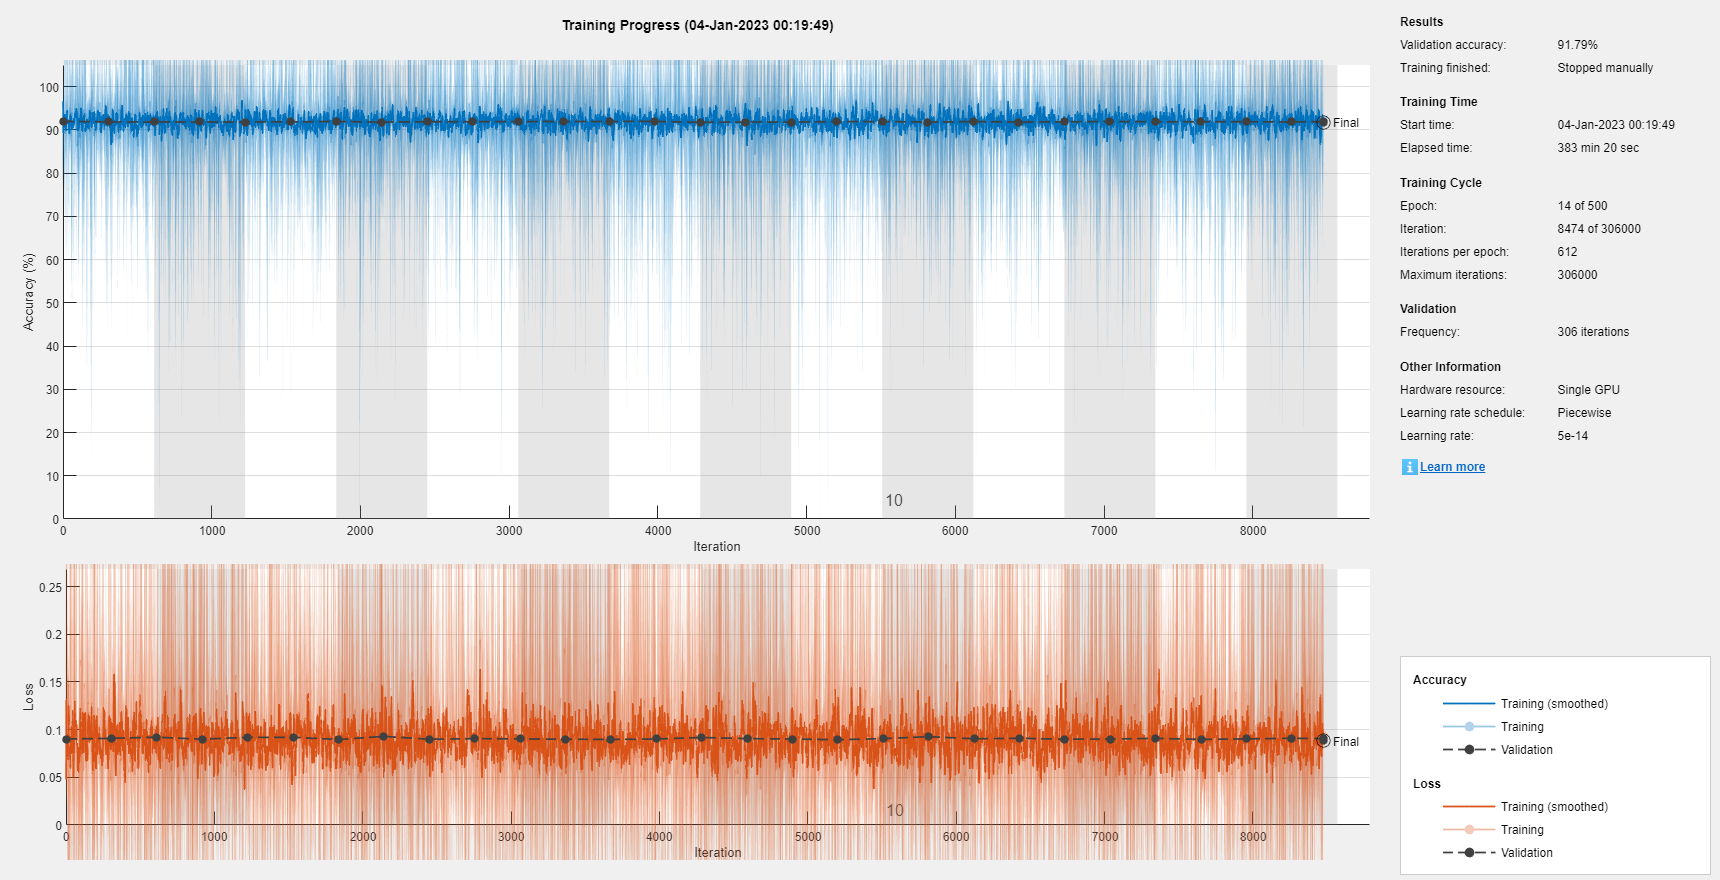

try
    [net,info] = trainNetwork(features_train,labels_train ,net,options);
catch
    [net,info] = trainNetwork(features_train,labels_train ,layerGraph(net),options);
end

sz = size(features_test,1);
ypred_test = cell(sz,1);
for j = 1:sz
ypred_test(j,1) = predict(net,features_test(j,1));
end

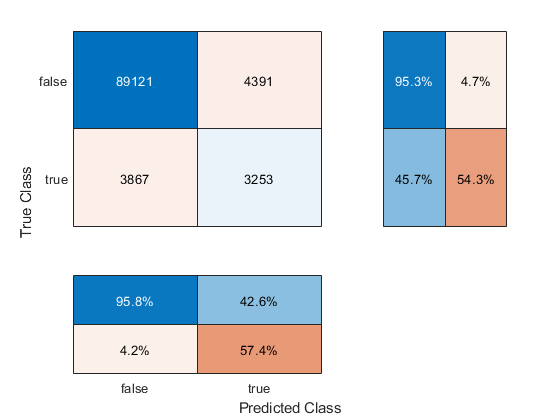

confusionMat =        89121        4391
        3867        3253


precision =     0.9530
    0.4569


recall =     0.9584
    0.4256


f1Scores =     0.9557
    0.4407


meanF1 = 0.6982

ypred_mat = [ypred_test{:,:}];
gt = [labels_test{:,:}]=="1";
pred_vec = imgaussfilt(ypred_mat(2,:),1)>0.5;
test_model(gt,pred_vec);

% main_name = '6-2-chamber-female-main.mat';
% mini_name = '6-2-chamber-female-mini.mat';

% main_name = '6-2-chamber-female-main-2.mat';
% mini_name = '6-2-chamber-female-mini-2.mat';

main_name = '6-2-free-male-main.mat';
mini_name = '6-2-free-male-mini.mat';




load(mini_name)
objmini = obj;
load(main_name)
objmain = obj;

objmini.setAudioFile(1)

ans = logical
   1


objmain.setAudioFile(1)

ans = logical
   1


obj = objmini;
obj_down = obj.downsample_obj(1000);
vec = obj_down.vec;


labels_vector = get_labels_vector(obj_down,{'subjectUSV','possiblibly subjectUSVV'});

Unrecognized function or variable 'obj_down'.

audio_vector = obj_down.vec;
    data_test_one.vector={reshape0(audio_vector,[2000,-1],'pad',0)};
    data_test_one.labels = {reshape0(labels_vector,[2000,-1],'pad',false)};
    
    [features_test_one,labels_test_one] = prepare_files(...
        data_test_one,...
        audio_len_bin, ...
        output_len_bin, ...
        0, ...
        overlap_len_bin);

sz = size(features_test_one,1);
ypred = cell(sz,1);
for j = 1:sz
ypred(j,1) = predict(net,features_test_one(j,1));
end


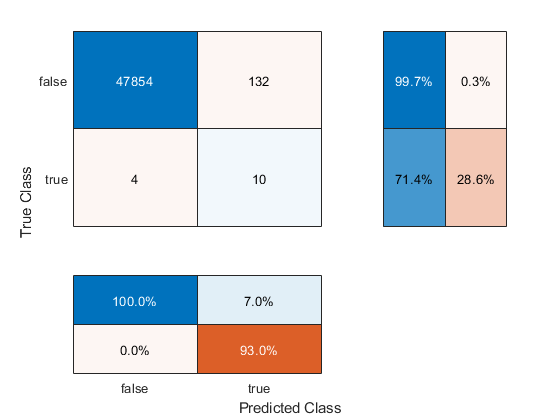

confusionMat =        47854         132
           4          10


precision =     0.9972
    0.7143


recall =     0.9999
    0.0704


f1Scores =     0.9986
    0.1282


meanF1 = 0.5634

ypred_mat = [ypred{:,:}];
gt = [labels_test_one{:,:}]=="1";
% pred_vec = imgaussfilt(ypred_mat(2,:),1)>0.5;
pred_vec = ypred_mat(2,:) >0.4;
test_model(gt,pred_vec);

ypred_mat = ypred_mat';
gt = gt';

th = 0.4;

% logical_vector = imgaussfilt(ypred_mat(:,2),0.1)>th;
% logical_vector = imgaussfilt(ypred_mat(:,2),[1,40])>th;
% logical_vector = imgaussfilt(ypred_mat(:,2),0.5)>th;
logical_vector = ypred_mat(:,2)>th;
% shift_sec = 0.5;
% % shift_sec = 0;
% feature_fs = numel(gt)/1000;
% shift_n = round(feature_fs*shift_sec);
% logical_vector = circshift(logical_vector,-shift_n);
% logical_vector(end-shift_n+1:end) = false;
timeshift = -0.01;
% timeshift = 0.025;
logical_vector = reshape(logical_vector,1,[]);
original_len_sec = objmini.audioLen;
min_syllable_length_milisec = 1;
fs_in = round(numel(logical_vector)/original_len_sec);
[tab, filtered_logical_vector]= create_table_from_logical_array(...
    logical_vector,original_len_sec,min_syllable_length_milisec,fs_in);

tab.Label = repmat("sniffUSV",[size(tab,1),1]);
tab_long = short_table_to_roiTable(obj,tab,timeshift);


logical_vector = gt';
original_len_sec = objmini.audioLen;
min_syllable_length_milisec = 0;
fs_in = round(numel(logical_vector)/original_len_sec);
[tab, filtered_logical_vector]= create_table_from_logical_array(...
    logical_vector,original_len_sec,min_syllable_length_milisec,fs_in);
tab.Label = repmat("GT",[size(tab,1),1]);
tab_long_gt = short_table_to_roiTable(objmain,tab,timeshift,10000);



objmini_copy = copyobj(objmini);

% vec_temp = objmini_copy.vec;
% vec_temp = vec_temp - smooth(vec_temp,100);
% objmini_copy.vec = vec_temp;

% tab_orig = objmini_copy.filtered_roi_table({'subjectUSV','Low'});
tab_orig = objmini_copy.filtered_roi_table({'subjectUSV'});
% tab_orig = objmini_copy.roiTableTemplate;
% combtab = [tab_orig;tab_long_gt;tab_long];
combtab = [tab_orig;tab_long];
combtab = sortrows(combtab,{'TimeStart','Label'});

objmini_copy.roiTable = combtab;
added_types = {...
    "FP_low_as_USV"   ,	[1 1 0],"";...
    "FP_noise_as_USV" , [0.9290 0.6940 0.1250],"";...
    "TP_new_USV"      ,	[0 1 1],"";...
    "GT"      ,[1,0,0],"";...
    "sniffUSV",[0,1,0],""};
objmini_copy.addedTypeList = [objmini.addedTypeList;added_types];
% 
objmini_copy.window = 512*2;
objmini_copy.overlap = 512;
objmini_copy.fft =  512*2;
objmini_copy.ylims = [50,80000];
objmini_copy.times_ = [536.7 538.7];


prob_struct.prob_vec = ypred_mat(:,2)';
prob_struct.detection_times = [0 1000];
objmini_copy.probability_vector = prob_struct;
objmini_copy.refresh_scores;

Scores were refreshed


% objmini_copy.times_ = [0 1];

% objmini_copy.window = 6250;
% objmini_copy.overlap = 3125;
% objmini_copy.fft =  6250;
% objmini_copy.ylims = [200,10000];

HybridMuse Version 2.0


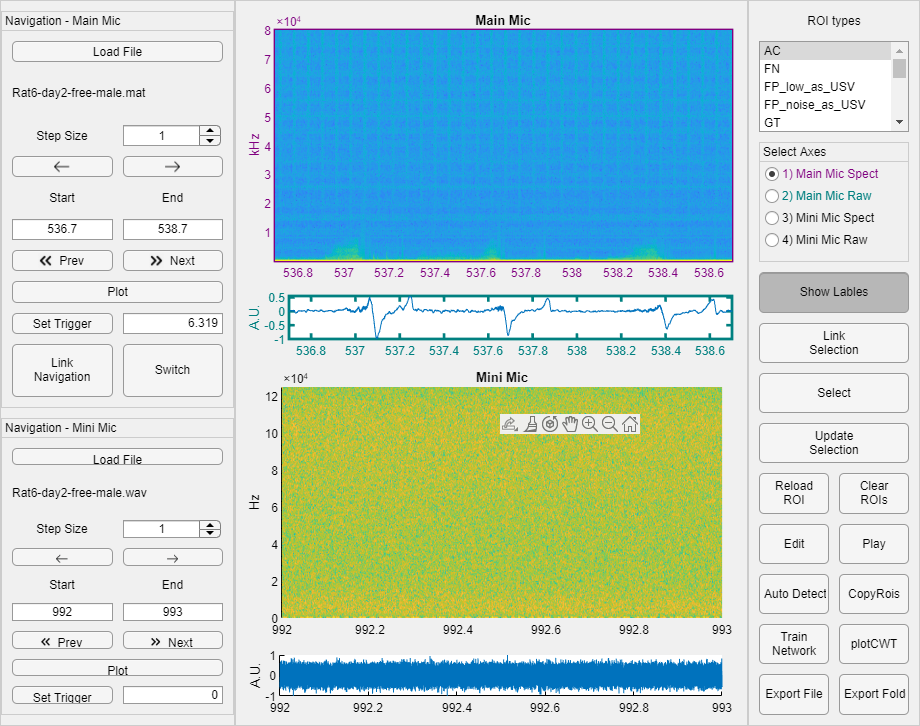

HybridMouse(objmini_copy,objmain)